# MR Signal Equations

Pulse sequences create an MR signal that depends on the specific parameters used for that sequence.  For several important pulse sequences, we have equations that describe the size of the signal we expect, given the parameters.  This tutorial describes and plots some of the signals.

This tutorial goes through the sequences and the equations for major types of acquisitions.

As a reminder, here are the T1 and T2 parameters of gray and white matter


$$\matrix{
\text{Component}    	& n_0 \text{mol} 	& n(\tau) \text{mol}	& p(\tau) = P n(\tau)/\Sigma n(\tau)    \cr
N_2			& 1 			& 1-\xi/2		& P(1-\xi/2)/(4-\xi)			\cr
H_2			& 3 			& 3-3\xi/2		& P(3-3\xi/2)/(4-\xi)			\cr
NH_3			& 0 			& \xi			& P\xi/(4-\xi)				\cr
\Sigma	        & 4 			& 4-\xi 		    & P					\cr
}$$


                **Tissue**  | **T1** (1.5T,3.0T,4T)   |     **T2** (1.5T,3.0T,4T) (sec)  | **T2*** (1.5T, 3T)

                ------------------------------------------------------------------------------------------------------

                White     0.64, 0.86, 1.04       |     0.080, 0.080, 0.050       |  0.067

                Gray       0.88, 1.20, 1.40       |     0.080, 0.110, 0.050       |  0.048 

                ------------------------------------------------------------------------------------------------------

            **Source**: Jezzard and Clare Chapter 3 in the Oxford fMRI Book.  The numbers differ somewhat between different publications (e.g.,  "[NMR relaxation times in the human brain at 3.0 tesla](https://pubmed.ncbi.nlm.nih.gov/10232510/)")

Also:  T2* at 1.5T from [http://www.ajnr.org/content/29/5/950](http://www.ajnr.org/content/29/5/950) Table 1.  They have a T2 of 96 ms in GM and 110 in WM.

And:  T2 at 3T 

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/) 

[https://link.springer.com/article/10.1007%2Fs11682-016-9550-5](https://link.springer.com/article/10.1007%2Fs11682-016-9550-5) 

[https://link.springer.com/article/10.1007/s10334-016-0573-0](https://link.springer.com/article/10.1007/s10334-016-0573-0)

[https://www.frontiersin.org/articles/10.3389/fnins.2013.00095/full](https://www.frontiersin.org/articles/10.3389/fnins.2013.00095/full) 

Olivia Wiessman:  [https://www-sciencedirect-com.stanford.idm.oclc.org/science/article/pii/S1053811917307176?via%3Dihub](https://www-sciencedirect-com.stanford.idm.oclc.org/science/article/pii/S1053811917307176?via%3Dihub) Good table 1, though measurements at 7T but listed for 3T

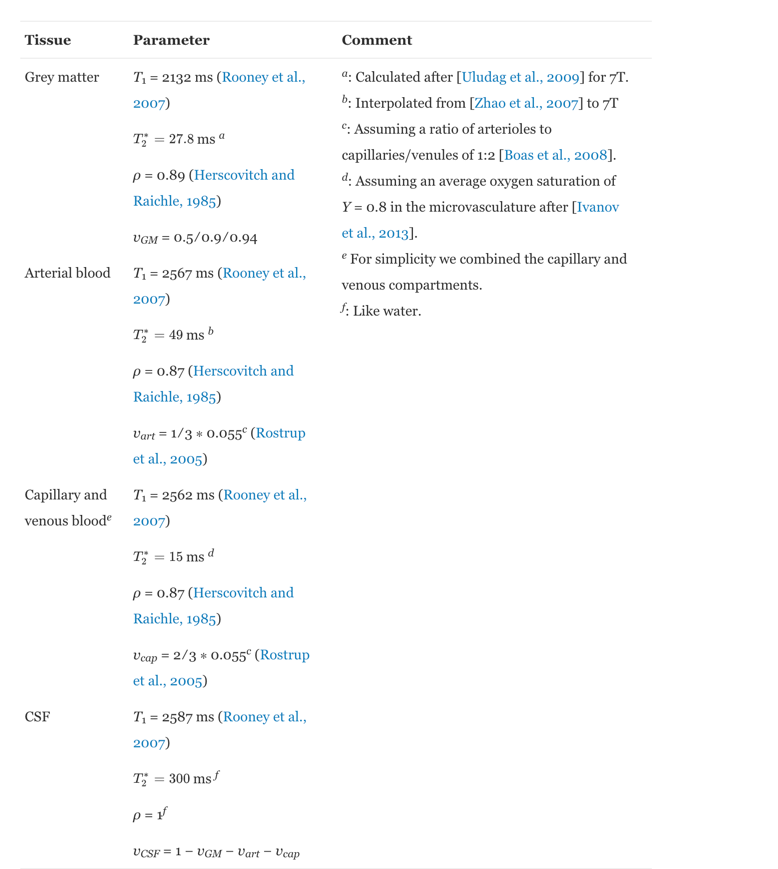

## Spin Echo

Four parameters define the spin echo signal equations.  Two are pulse sequence choices:  TR (repetition time), TE (echo time) and two are material properties (T1 and T2).

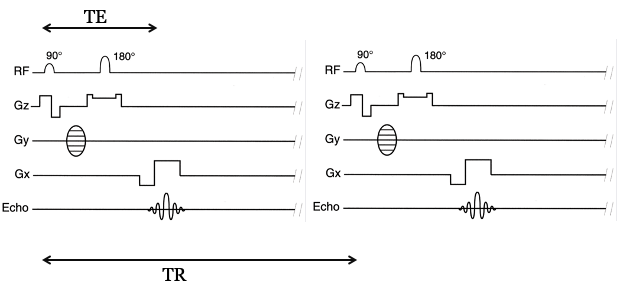

Here is the equation relating SE signal to these parameters:


$$\textrm{signal}\left(\textrm{SE}\right)=\left(1-\exp \left(-\frac{\textrm{TR}}{\textrm{T1}}\right)\right)\;\left(e\textrm{xp}\left(-\frac{\textrm{TE}}{\textrm{T2}}\right)\right)$$


## Calculating the Spin Echo signal

TR = 2;   % sec
T1 = 1.1; % sec
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

## Gradient Echo

The Gradient Echo Sequence has this pulse diagram

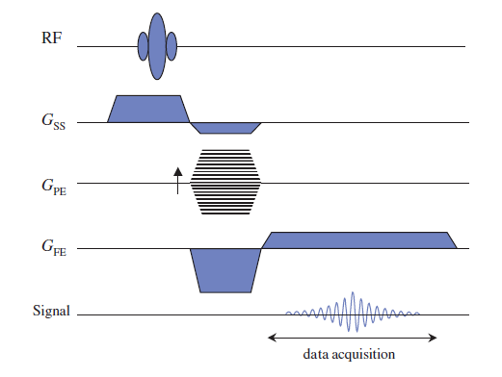

The key parameters for the sequence are the flip angle $$\alpha$$, TR, TE, T1 and T2*.  The formula is

#### 
$$Signal(GE) = M_0 {\frac{sin(\alpha) (1 - exp^{(-TR/T1)} )e^{(-TE/T2*)}}{1 - cos(\alpha)(1 - exp^{-(TR/T1)})}$$


## Calculating the GE signal

We can write the parameters and Matlab expression this way

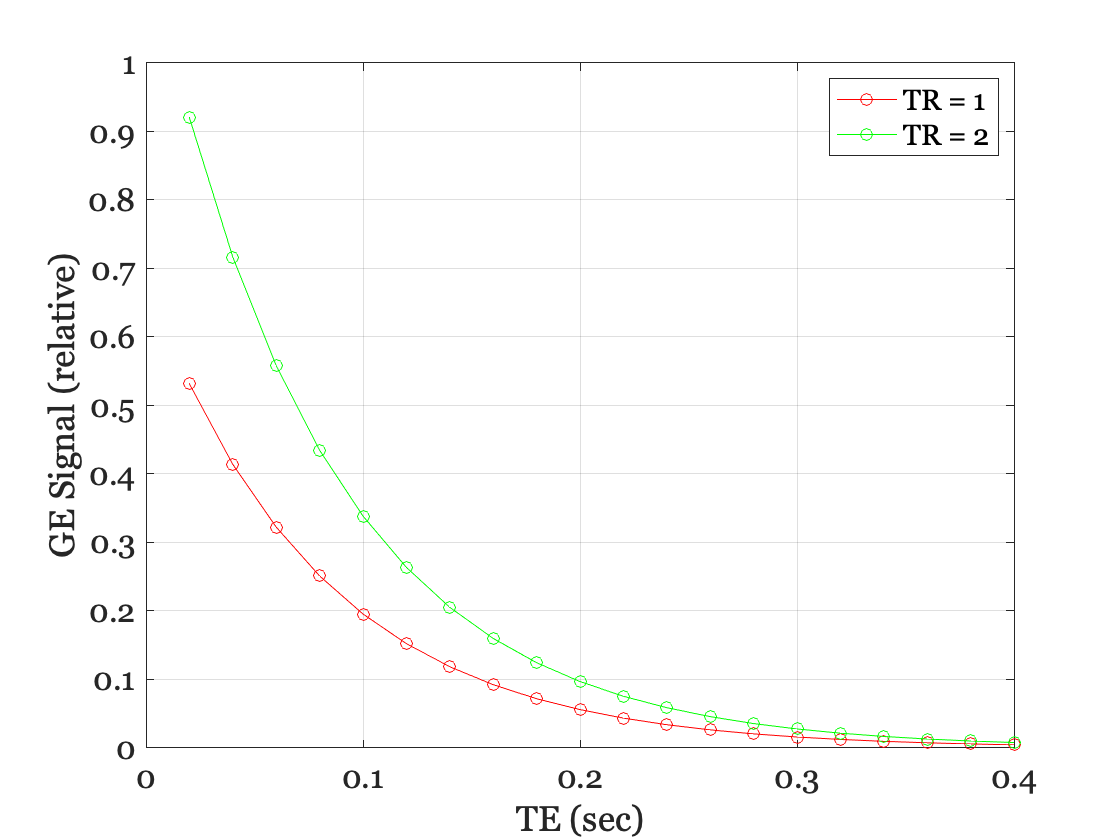

M0 = 1;      % To ignore, treating as relative
FA = 60;     % deg
TR = 1;      % sec
T1 = 1.2;    % sec
T2star = 0.08;  % sec

% Sweep out a set of measurement times for the graident echo
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

% sind is sine for degree inputs
% The Gradient Echo Signal Equation
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cosd(FA)*(1 - exp(-TR/T1)));

figure; 
plot(TE,sig,'-o');
grid on;

hold on;
TR = 2;
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cosd(FA)*(1 - exp(-TR/T1)));
plot(TE,sig,'-o');
legend({'TR = 1','TR = 2'})
xlabel('TE (sec)'); ylabel('GE Signal (relative)');

In a pair of experiments I am analyzing with Hua and Dora, we used two different GE pulse sequence with these parameters.

**Gradient Echo parameters**

Sequence    TE      TR       FA

Resting       0.028     2        77

SMS           0.0116  0.25    48

______________________________________

**Tissue parameters**

 Tissue         T1        T2

         CSF       4.2734      1.5776 

     Gray         1.2           0.11

      White        0.8          0.080

Arterial Blood       1.7        0.049 [T2*](https://www.frontiersin.org/articles/10.3389/fnins.2013.00095/full) 

Venous Blood     1.7        0.015 T2*

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7897197/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7897197/) 

Set the parameters

% Resting Sequence parameters
rTE = 0.0275; rFA = 77; rTR = 2;

% SMS sequence parameters
sTE = 0.011; sFA = 48; sTR = 0.25;

% Tissue parameters (approximate, and varying across brain
gT1 = 1.2;  gT2star = 0.11;  
wT1 = 0.8;  wT2star = 0.08; 
cT1 = 4.27; cT2star = 1.58;


Calculate signal ratios for the gray matter and the two sequences

% The Gradient Echo Signal Equation for gray matter, resting state
meanGRSig = sind(rFA)*(1 - exp(-rTR/gT1))*(exp(-rTE/gT2star)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/gT1)));

% SMS
meanGSSig = sind(sFA)*(1 - exp(-sTR/gT1))*(exp(-sTE/gT2star)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/gT1)));

fprintf('Ratio of mean gray matter signal levels (GE/SMS) %f\n',meanGRSig/meanGSSig);

Ratio of mean signal levels 5.204428


Now for the white matter

% The Gradient Echo Signal Equation for white matter, resting state
meanWRrSig = sind(rFA)*(1 - exp(-rTR/wT1))*(exp(-rTE/wT2star)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/wT1)))

meanWRrSig = 0.7993


% SMS
meanWSSig = sind(sFA)*(1 - exp(-sTR/wT1))*(exp(-sTE/wT2star)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/wT1)))

meanWSSig = 0.2119


% Ratios of the absolute mean signals
fprintf('Ratio of mean white matter signal levels (GE/SMS) %f\n',meanWRrSig/meanWSSig);

Ratio of mean white matter signal levels (GE/SMS) 3.772262


So the mean signals are quite different.  But we are measuring the contrast.  So let's see how much the signal changes when T1 changes.  It seems a bigger change in SMS than resting

wT1new = wT1 + 0.1;

% Resting state
(sind(rFA)*(1 - exp(-rTR/wT1new))*(exp(-rTE/wT2star)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/wT1new)))) / meanWRrSig

ans = 0.9642


% SMS - contrast
(sind(sFA)*(1 - exp(-sTR/wT1new))*(exp(-sTE/wT2star)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/wT1new)))) / meanWSSig

ans = 0.8850

What about if  T2star changes?  A small change in SMS, but a larger change in resting

wT2starnew = wT2star + 0.005;

% Resting
(sind(rFA)*(1 - exp(-rTR/wT1))*(exp(-rTE/wT2starnew)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/wT1)))) / meanWRrSig

ans = 1.0204


% SMS
(sind(sFA)*(1 - exp(-sTR/wT1))*(exp(-sTE/wT2starnew)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/wT1)))) / meanWSSig

ans = 1.0081

Now gray matter

gT1new = gT1 + 0.1;

% Resting state
(sind(rFA)*(1 - exp(-rTR/gT1new))*(exp(-rTE/gT2star)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/gT1new)))) / meanGRSig

ans = 0.9613


% SMS - contrast
(sind(sFA)*(1 - exp(-sTR/gT1new))*(exp(-sTE/gT2star)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/gT1new)))) / meanGSSig

ans = 0.9210

gT2starnew = gT2star + 0.005;

% Resting
(sind(rFA)*(1 - exp(-rTR/gT1))*(exp(-rTE/gT2starnew)) / ...
    (1 - cosd(rFA)*(1 - exp(-rTR/gT1)))) / meanGRSig

ans = 1.0109


% SMS
(sind(sFA)*(1 - exp(-sTR/gT1))*(exp(-sTE/gT2starnew)) / ...
    (1 - cosd(sFA)*(1 - exp(-sTR/gT1)))) / meanGSSig

ans = 1.0044

## [Spoiled Gradient Echo Recalled (link)](https://mriquestions.com/spoiling---what-and-how.html)

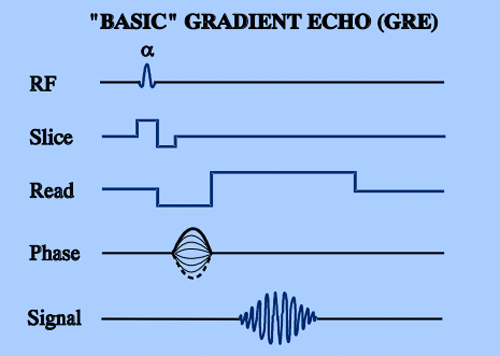 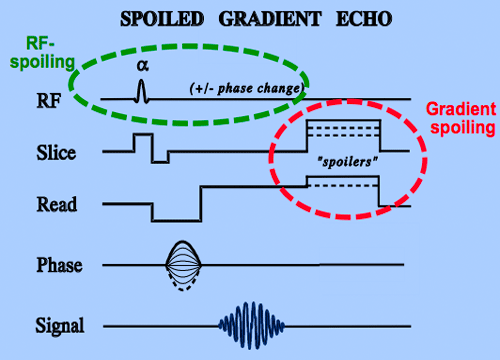

## Inversion Recovery